% Параметры системы
M = 20; % масса тележки
m1 = 2; % масса 1-го груза
m2 = 1; % масса 2-го груза
l1 = 1; % длина 1-го маятника
l2 = 2; % длина 2-го маятника
g = 10; % ускорение свободного падения

% ВСВ
A = [0 1 0 0 0 0;
     0 0 m1*g/M 0 m2*g/M 0;
     0 0 0 1 0 0;
     0 0 (M+m1)*g/(M*l1) 0 m2*g/(M*l1) 0;
     0 0 0 0 0 1;
     0 0 m1*g/(M*l2) 0 (M+m2)*g/(M*l2) 0];

B = [0;
     1/M;
     0;
     1/(M*l1);
     0
     1/(M*l2)];

D = [0 0;
     1/(M*l1) 1/(M*l2);
     0 0;
     1/l1^2*(1/M+1/m1) 1/(M*l1*l2);
     0 0;
     1/(M*l1*l2) 1/l2^2*(1/M+1/m2)];

C = [1 0 0 0 0 0;
     0 0 1 0 0 0;
     0 0 0 0 1 0];

A2 = [0 1  0 0;
     -1 0  0 0;
      0 0  0 2;
      0 0 -2 0];
eig(A2)

ans =    0.0000 + 1.0000i
   0.0000 - 1.0000i
   0.0000 + 2.0000i
   0.0000 - 2.0000i


B2 = [1 0 1 0;
      0 1 0 1];
C2 = [0 0 1 0 1 0];
D2 = [0 0 0 0];

% начальные условия:
x_0 = 0.2;
v_0 = 0;
phi1_0 = 0.05;
w1_0 = 0;
phi2_0 = 0.05;
w2_0 = 0;
x0 = [x_0; v_0; phi1_0; w1_0; phi2_0; w2_0];
w0 = [0.1; 0.1; 0.1; 0.1];

% матрица регулятора K1
a = 0.1;
cvx_begin sdp;
variable P1(6,6);
variable Y1(1,6);
P1 > 0.0001*eye(6)

P1*A'+A*P1+2*a*P1+Y1'*B'+B*Y1 <= 0;

cvx_end;

 
Calling SDPT3 4.0: 48 variables, 23 equality constraints
------------------------------------------------------------

 num. of constraints = 23
 dim. of sdp    var  = 12,   num. of sdp  blk  =  2
 dim. of free   var  =  6 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.4e+02|6.3e+01|3.3e+03| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.885|0.873|1.6e+01|8.1e+00|2.5e+02| 0.000000e+00  4.907399e-03| 0:0:00| chol  1  1 
 2|0.809|0.743|3.1e+00|2.1e+00|6.7e+01| 0.000000e+00  5.742865e-03| 0:0:00| chol  1  1 
 3|0.945|0.754|1.7e-01|5.2e-01|1.4e+01| 0.000000e+00  5.797198e-03| 0:0:00|

K1 = Y1*inv(P1)

K1 = 1.0e+03 *

   -0.0061   -0.0335   -3.0154   -0.9464    3.5787    1.6021


eig(A+B*K1)

ans =   -1.4810 + 3.8854i
  -1.4810 - 3.8854i
  -3.1113 + 0.0000i
  -2.3099 + 0.0000i
  -0.2804 + 0.2107i
  -0.2804 - 0.2107i


% матрица регулятора K2
cvx_begin sdp;
variable P2(6,4);
variable Y2(1,4);
P2*A2-A*P2 == B*Y2 + D*B2;
C2*P2+D2 == 0;
cvx_end;

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


K2 = Y2-K1*P2

K2 =  -211.1748   92.6559 -192.3795   23.4097


out = sim('model5.slx',100);

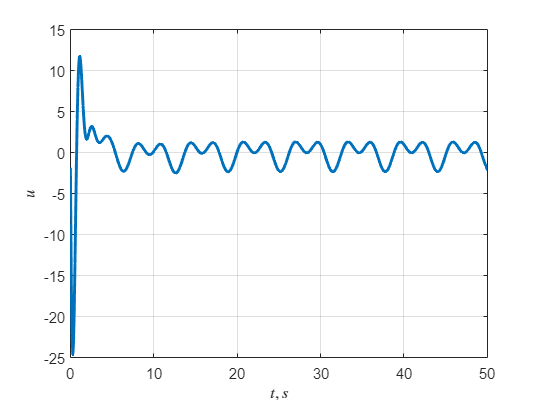

% управление 
plot(out.u.Time, out.u.Data, LineWidth=2), grid on
xlabel('$t,s$', 'Interpreter','latex')
ylabel('$u$', 'Interpreter','latex')
xlim([0 50])

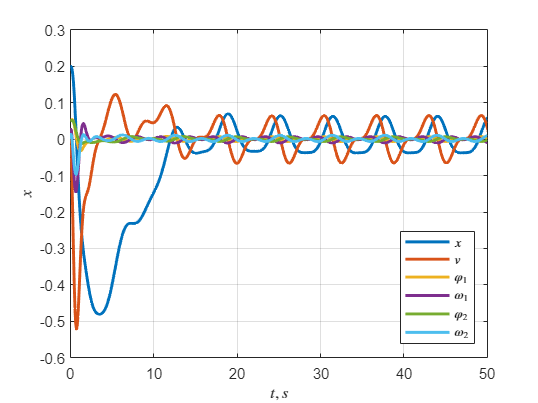


% вектор состояния
plot(out.x_linear.Time, out.x_linear.Data, LineWidth=2), grid on
xlabel('$t,s$', 'Interpreter','latex')
ylabel('$x$', 'Interpreter','latex')
legend('$x$', '$v$', '$\varphi_1$', '$\omega_1$', '$\varphi_2$', '$\omega_2$', 'Interpreter','latex')
xlim([0 50])
legend("Position",[0.74543,0.15056,0.13497,0.27459])

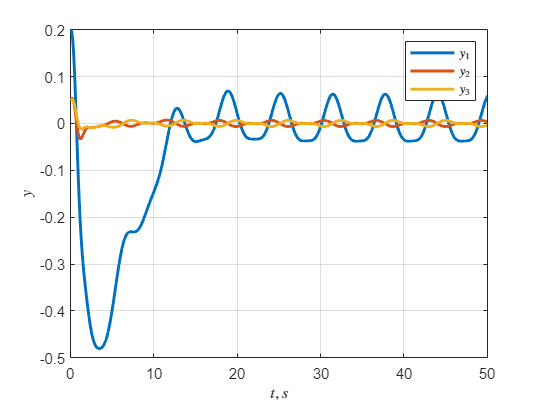


% выход
plot(out.y_linear.Time, out.y_linear.Data, LineWidth=2), grid on
xlabel('$t,s$', 'Interpreter','latex')
ylabel('$y$', 'Interpreter','latex')
legend('$y_1$', '$y_2$', '$y_3$', 'Interpreter','latex')
xlim([0 50])

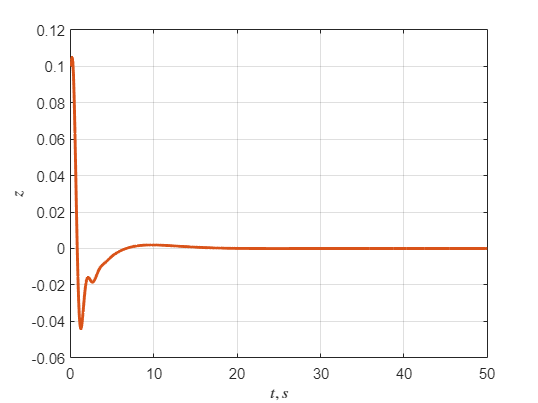


% регулируемый выход % 1: #D95319, 2: #EDB120
plot(out.z.Time, out.z.Data, LineWidth=2), grid on
xlabel('$t,s$', 'Interpreter','latex')
ylabel('$z$', 'Interpreter','latex')
xlim([0 50])

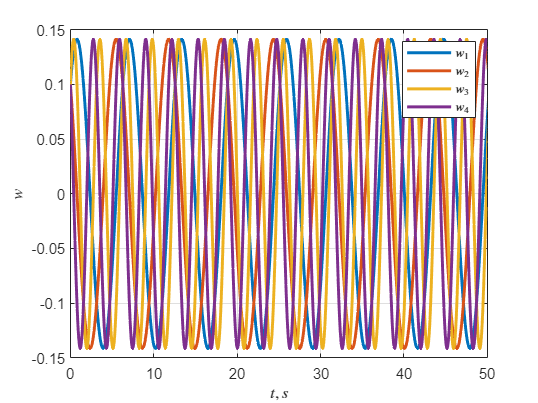


% внешние возмущения w
plot(out.w.Time, out.w.Data, LineWidth=2), grid on
xlabel('$t,s$', 'Interpreter','latex')
ylabel('$w$', 'Interpreter','latex')
legend('$w_1$', '$w_2$', '$w_3$', '$w_4$', 'Interpreter','latex')
xlim([0 50])

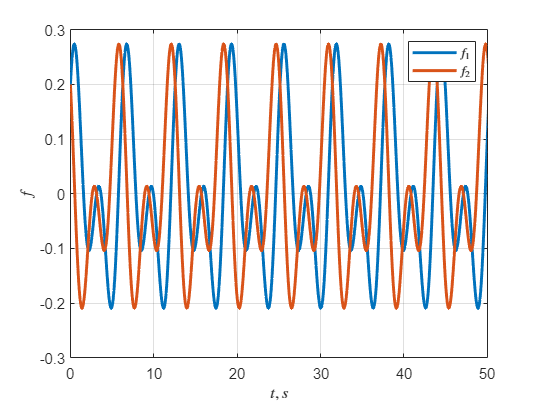

%ylim([-0.15 0.15])

% внешние возмущения f
plot(out.f.Time, out.f.Data, LineWidth=2), grid on
xlabel('$t,s$', 'Interpreter','latex')
ylabel('$f$', 'Interpreter','latex')
legend('$f_1$', '$f_2$', 'Interpreter','latex')
xlim([0 50])

%ylim([-0.15 0.15])